load('TennisData.mat')

R = TennisData(:,1);
Rank = table2array(R);
a = TennisData(:,2);
b = TennisData(:,3);
c = TennisData(:,4);
d = TennisData(:,5);
Aa= table2array(a);
Bb= table2array(b);
Cc= table2array(c);
Dd= table2array(d);
A = 100*Aa;
B = 100*Bb;
C = 100*Cc;
D = 100*Dd;
e = TennisData(:,6);
f = TennisData(:,7);
E = table2array(e);
F = table2array(f);
ServeR = A + B + C + D + E - F;

bar(Rank,ServeR)
ylim([260 320])
title('Tennis- Serve vs Rank')
xlabel('Rank')
ylabel('Serve Index')

Corr = corrcoef(Rank,ServeR);
Correlation = Corr(1,2)

Correlation = -0.3580

test = strcat('Correlation factor = ',num2str(Correlation,4))

test = 'Correlation factor =-0.358'

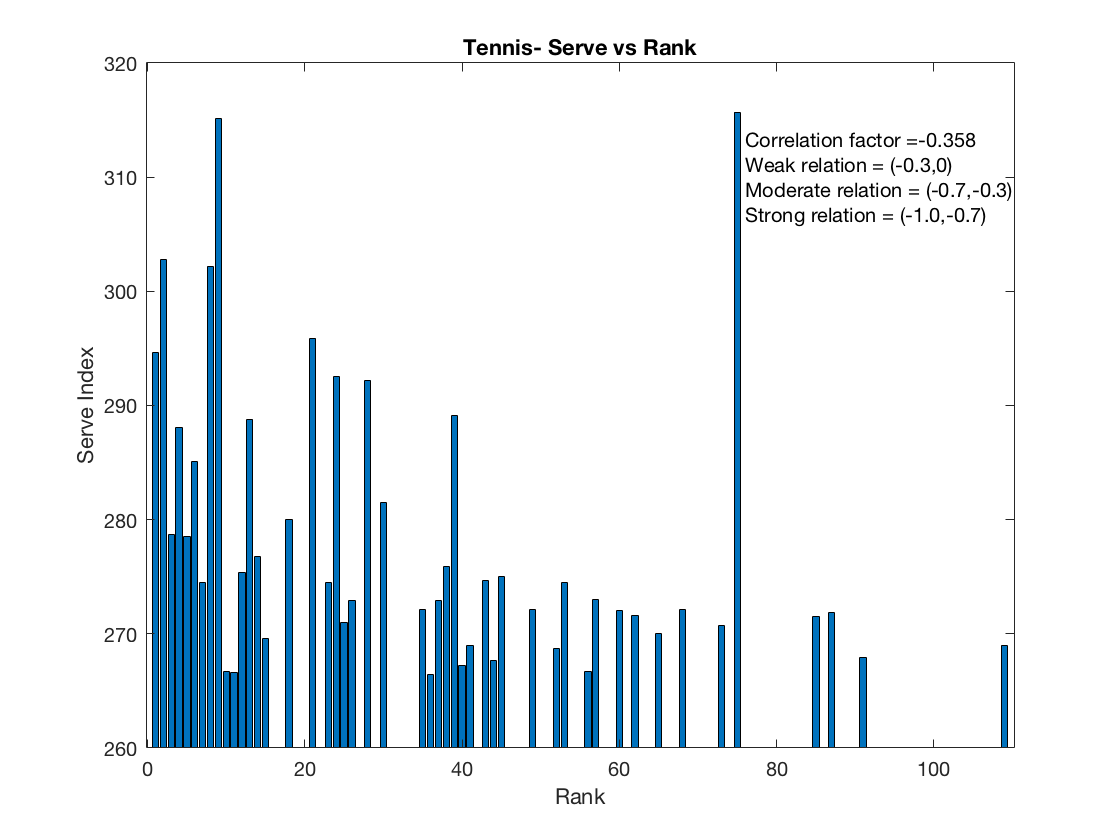

descr = {test;
'Weak relation = (-0.3,0)';
'Moderate relation = (-0.7,-0.3)';
'Strong relation = (-1.0,-0.7)'};
text(76,310,descr)